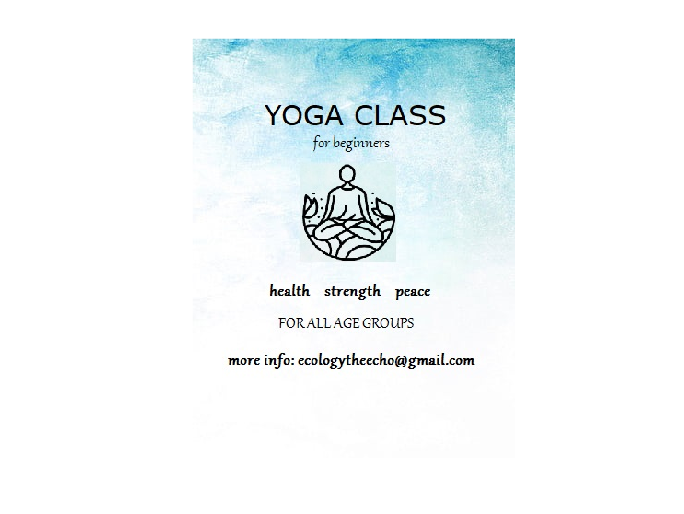

% reading an image from Matlab drive.
I = imread("Yoga.jpg");

%displaying the image
imshow(I);

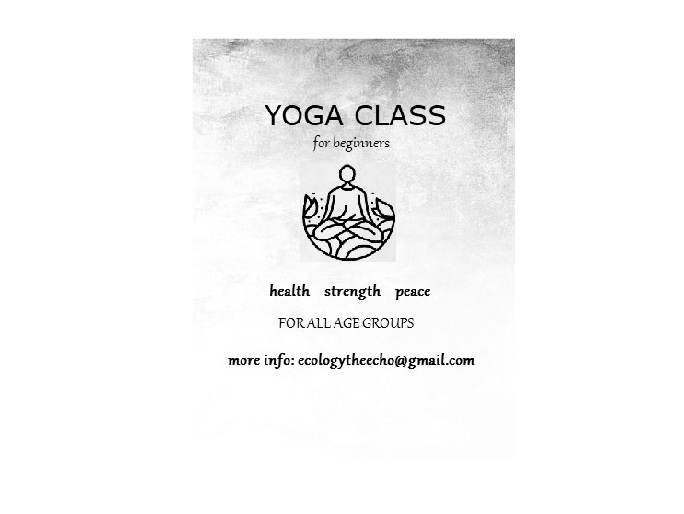


%Converting image to black & white
gs = im2gray(I);

%Automatically adjusting the grayscale
gs = imadjust(gs);
imshow(gs);

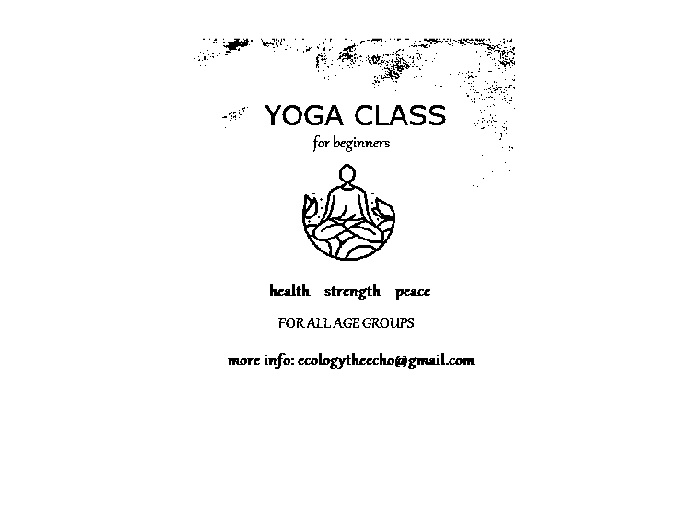


%Adjusting binariy threshold
BW = imbinarize(gs,"adaptive","ForegroundPolarity","dark");
imshow(BW)

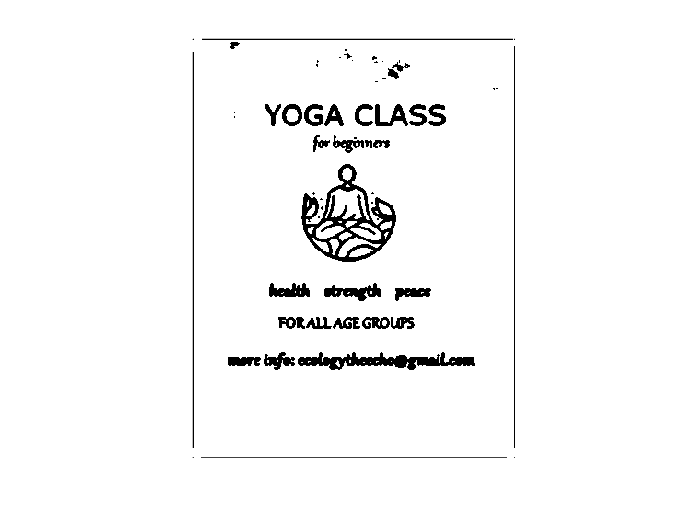


%Removing noise from the image
H = fspecial("average",3);
gssmooth = imfilter(gs,H);
BWsmooth = imbinarize(gssmooth,"adaptive","ForegroundPolarity","dark");
imshow(BWsmooth)

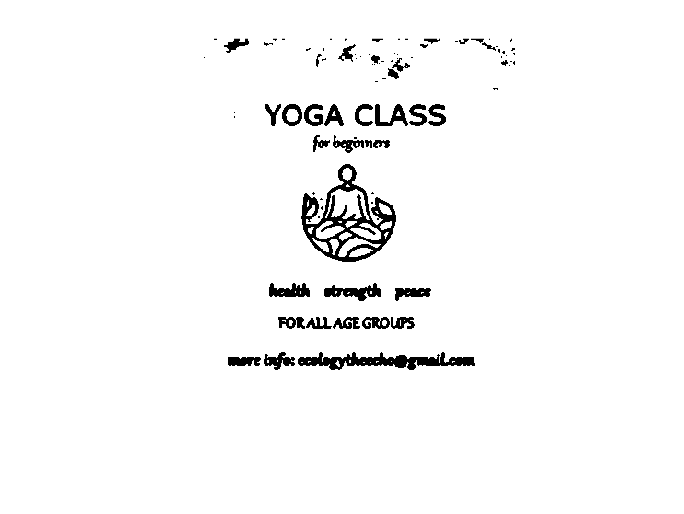


%Replicating the pixels outside the border
gssmooth = imfilter(gs,H,"replicate");
BWsmooth = imbinarize(gssmooth,"adaptive","ForegroundPolarity","dark");

%displaying the result
imshow(BWsmooth)


%saving the result image in a .png file
imwrite(BWsmooth, '/home/matlab/BWsmooth.png');

